# Lab 9: Ultrasonic Range Finder

**By Ari Porad, May 11th 2021**

**Introduction to Sensors, Instrumentation, and Measurement**

## **Abstract**

Ultrasonic transducers were used to bounce sound waves off a wall, thereby measuring the distance. This method proved successful in practice, although more research is nessecary to improve performance and reduce noise.

## Methods

### Transmitting

The transmitter was powered by two signals from the O-Scope, passed through an AND gate. The first was a 40kHz signal with a 50% duty cycle, while the other was a 100 Hz signal with a pulse width of 0.2ms. This resulted in the transmitter outputting a 40kHz pulse for 0.2ms 100 times per second.

### Receiving

The ultrasonic transducers used--especially the one used for receiving--produced incredibly weak and noisy signals. Consequently, they had to be amplified and filtered significantly. We used two bandpass filters in series (each with a charictaristic frequency of roughly 40kHz and built-in amplification), and a final amplifier, for a total gain of ~40dB.

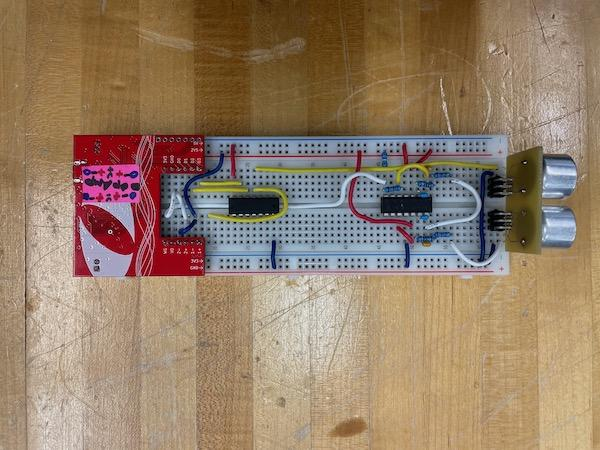

**Figure 1.** Photo of our breadboard with our completed circuit, as described above.

## Results

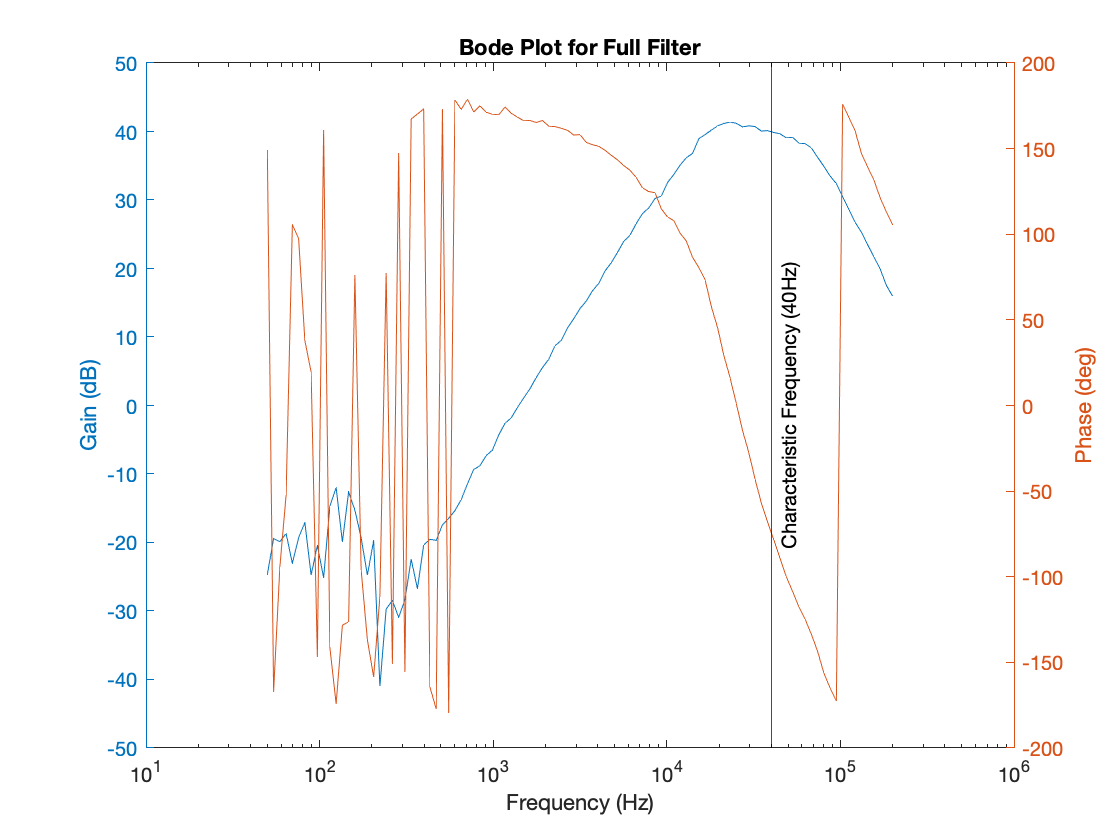

figure(3); clf;
data = readtable("bode_full.csv");

yyaxis left;
semilogx(data.freq, data.gain);
ylabel("Gain (dB)");

yyaxis right;
semilogx(data.freq, data.phase);
ylabel("Phase (deg)");
xlabel("Frequency (Hz)");
xline(40000, 'k', 'Characteristic Frequency (40Hz)', ...
    "LabelVerticalAlignment", "middle");    
title("Bode Plot for Full Filter");

**Figure 2.** Bode plot for our full receiver filtering system, showing its charactaristic frequency at 40kHz.

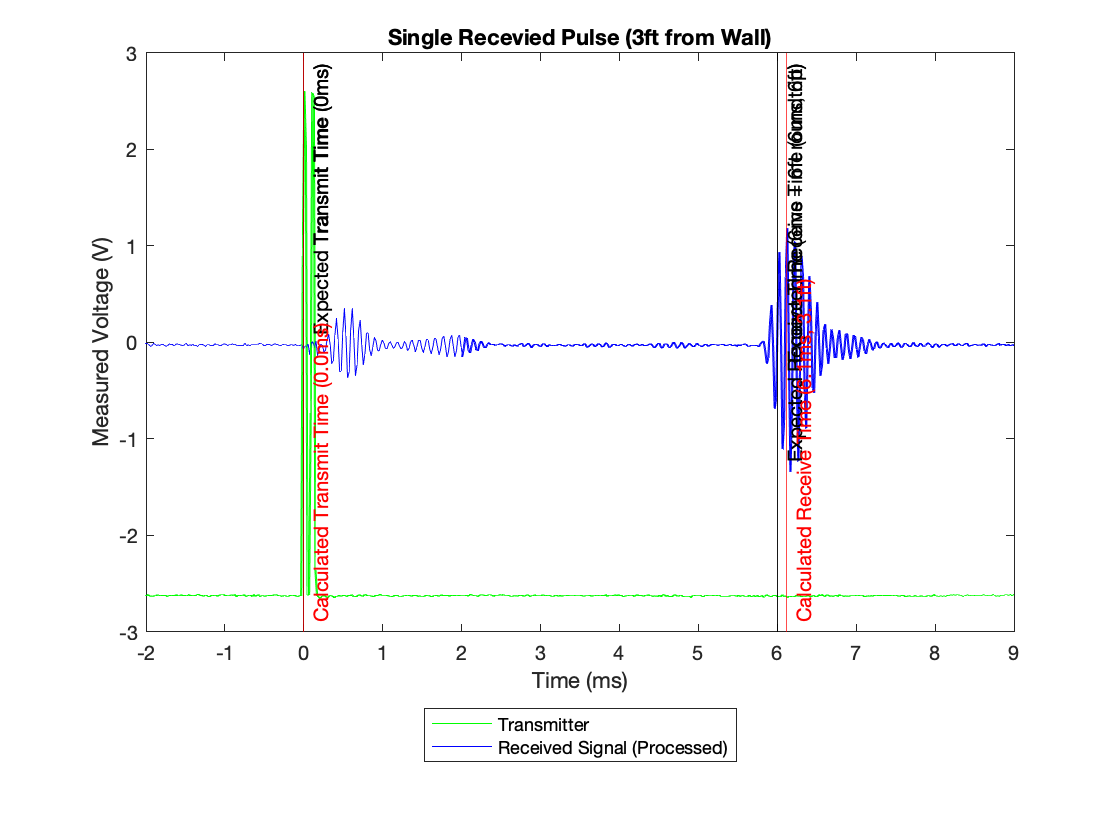

figure(4); clf;

data = readtable("raw_3ft.csv");

plot(10 + data.t1 * 1000, data.ch1, 'g-', "DisplayName", "Transmitter"); hold on;
plot(10 + data.t2 * 1000, data.ch2, 'b-', "DisplayName", "Received Signal (Processed)");
xlabel("Time (ms)");
ylabel("Measured Voltage (V)");
title("Single Recevied Pulse (3ft from Wall)");
xlim([-2, 9]);

% sound travels at ~1ft/ms, so 6ms is 6ft roundtrip / 3ft
xline(6, "k-", "Expected Receive Time (6ms = 6ft roundtrip)");
xline(0, "k-", "Transmit Time (0ms)");

legend show;
figure(5); clf;

ds = 1:5;

points = NaN(length(ds), 2);

for d = ds
    data = readtable(sprintf("raw_%1.0fft.csv", d));
    ch1 = data.ch1;
    ch2 = data.ch2;
    t1 = 1000 * (data.t1 - min([data.t1; data.t2]));
    t2 = 1000 * (data.t2 - min([data.t1; data.t2]));
    send_i = find(ch1 > 2, 1);
    send_t = t1(send_i);
    start_t = send_t - 2;
    start_t1 = start_t1;
    end_t1 = send_t + 5;
    start_t2 = send_t;
    end_t2 = start_t + 12;
    end_t = end_t2;
    

    mask1 = t1 >= start_t & t1 <= (end_t - 2);
    mask2 = t2 >= (start_t + 4) & t2 <= end_t;
    t1 = t1(mask1) - start_t;
    ch1 = data.ch1(mask1);
    t2 = t2(mask2) - start_t;
    ch2 = data.ch2(mask2);
    send_t = 2;
    
    t1 = t1 - send_t;
    t2 = t2 - send_t;
    send_t = 0;
    rec_t = rec_t - send_t;
    
    [~, rec_i] = max(ch2);
    rec_t = t2(rec_i);
    
    calc_dist = (rec_t - send_t) / 2;
    
    points(d, 1) = d;
    points(d, 2) = calc_dist;
    
    if d == 3
        figure(4);
        
        
        plot(t1, ch1, 'g-', "DisplayName", "Transmitter"); hold on;
        plot(t2, ch2, 'b-', "DisplayName", "Received Signal (Processed)");
        xlabel("Time (ms)");
        ylabel("Measured Voltage (V)");
        title(sprintf("Single Recevied Pulse (%1.0fft from Wall)", d));
        
        % sound travels at ~1ft/ms, so 6ms is 6ft roundtrip / 3ft
        xline(d * 2, "k-", sprintf("Expected Receive Time (%1.0fms, %1.0fft)", ...
            d * 2, d * 2));
        xline(0, "k-", "Expected Transmit Time (0ms)");
        xline(send_t, "r-", sprintf("Calculated Transmit Time (%1.1fms)", send_t), ...
            "LabelVerticalAlignment", "bottom");
        xline(rec_t, "r-", sprintf("Calculated Receive Time (%1.1fms, %1.1fft)", ...
            rec_t, calc_dist), "LabelVerticalAlignment", "bottom");
        
        legend("Transmitter", "Received Signal (Processed)", "","","","", "Location", "southoutside"); hold off;
    end
end

**Figure 3.** The received data for one pulse, taken at 3 feet from the wall. Representative sample of all pulses.

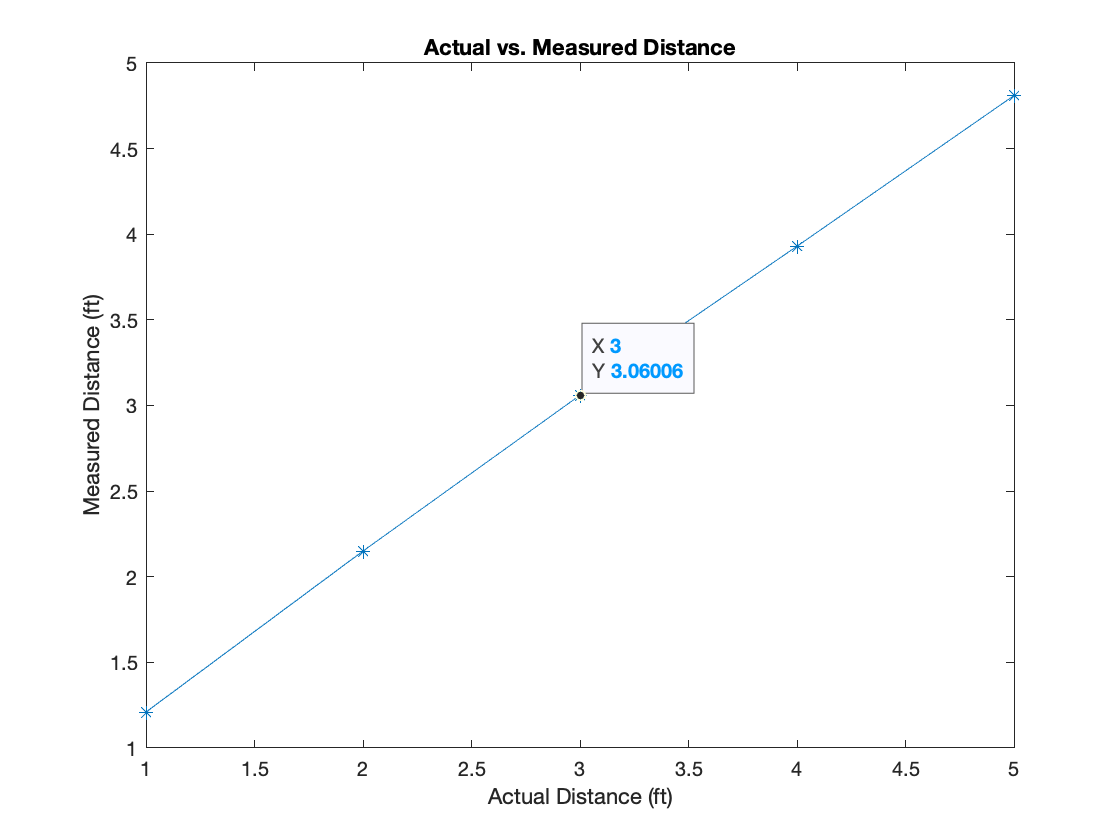

figure(5); clf;
plot(points(:, 1), points(:, 2), '*-');
xlabel("Actual Distance (ft)")
ylabel("Measured Distance (ft)")
title("Actual vs. Measured Distance");

**Figure 4.** Actual vs. measured distance for several positions.

## Finishing Remarks

Our range finder seems to work fairly well, demonstrating a strong linear relationship between actual and measured distance—although more tuning is require to achive precise distance measurements (both in the measurement process and in the testing process). Informally, our range finder seems to have an accuracy of ±1in.

Thank you to the ISIM teaching team for a great semester!